MP_convert_nd2_to_h5_raw('iSCAT1_well10_fov0_2025415_14415404.nd2', 'MP_data_well10.h5');

Dimensions : 1200 x 1200 pixels - 1 images.
Fichier sauvegardé sans traitement : MP_data_well10.h5


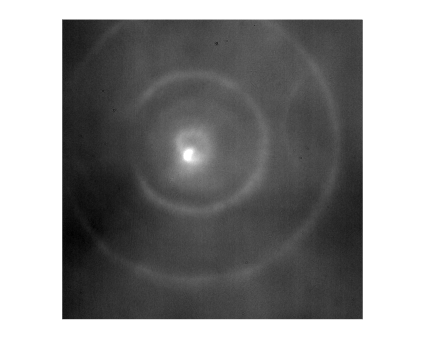

imshow(h5read('MP_data_well10.h5', '/data', [1 1 1 1 1], [1200 1200 1 1 1]), []);

clear all; clc;

% file path to flatfield ND2
flatfield_file = 'M:/Damien Bazin/iSCAT/2025_04_15_betaGal_massphoto_5/fastFF1_2025415_14430446.nd2';

% file path to .h5 
h5file = 'M:/Damien Bazin/iSCAT/2025_04_15_betaGal_massphoto_5/MP_data_well10.h5';
output_h5file = 'M:/Damien Bazin/iSCAT/2025_04_15_betaGal_massphoto_5/MP_data_flatfielded.h5';

% Calculate the avarage flatfield
reader = bfGetReader(flatfield_file);
nT_ff = reader.getSizeT();
dimX = reader.getSizeX();
dimY = reader.getSizeY();

disp('Calculation of the average flatfield...');

Calculation of the average flatfield...


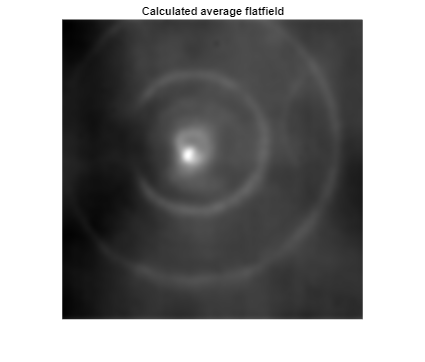

flatfield_stack = zeros(dimX, dimY, nT_ff, 'single');

for t = 1:nT_ff
    frame = bfGetPlane(reader, t);
    flatfield_stack(:,:,t) = single(frame);
end

flatfield = median(flatfield_stack, 3);
flatfield = imgaussfilt(flatfield, 10);
% flatfield = flatfield ./ imgaussfilt(flatfield, 10);
%flatfield = flatfield / median(flatfield, "all"); % Normalise around of 1
reader.close();

figure;
imshow(flatfield, []);
title('Calculated average flatfield');

## Apply flatfield to MP_data_well10.h5 containing only one image



% Input and output file
h5file = 'M:/Damien Bazin/iSCAT/2025_04_15_betaGal_massphoto_5/MP_data_well10.h5';
output_h5file = 'M:/Damien Bazin/iSCAT/2025_04_15_betaGal_massphoto_5/MP_data_well10_flatfielded.h5';

if exist(output_h5file, 'file')
        delete(output_h5file);
        pause(0.1); % delete an old .h5 output file if it already exists
    end

% load image size
info = h5info(h5file, '/data');
dimX = info.Dataspace.Size(1);
dimY = info.Dataspace.Size(2);

% Read the image
frame_now = h5read(h5file, '/data', [1 1 1 1 1], [dimX dimY 1 1 1]);

% frame = frame ./ flatfield;                     %flatfield it
% frame = frame ./ imgaussfilt(frame, 10);        %pseudo flatfield
% frame = frame / median(frame, "all");           %normalize]

% flatfield Correction
frame_now = frame_now ./ flatfield;                      %flatfield it
frame_now = frame_now ./ imgaussfilt(frame_now, 100);   %pseudo flatfield
frame_now = frame_now / median(frame_now, "all");        %normalize

% Create and write the corrected image
h5create(output_h5file, '/data', [dimX, dimY, 1, 1, 1], ...
    'Datatype', 'single', 'ChunkSize', [dimX, dimY, 1, 1, 1]);
h5write(output_h5file, '/data', frame_now, [1 1 1 1 1], [dimX dimY 1 1 1]);

disp('Corrected image saved in output file');

Corrected image saved in output file


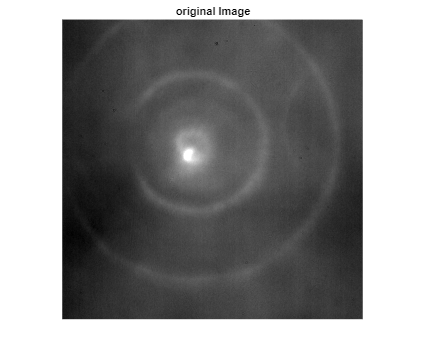

% Lire l'image originale
original_frame = h5read(h5file, '/data', [1 1 1 1 1], [dimX dimY 1 1 1]);
corrected_frame2 = h5read(output_h5file, '/data', [1 1 1 1 1], [dimX dimY 1 1 1]);

% Affichage côte à côte
figure;
imshow(original_frame, []);
title('original Image');

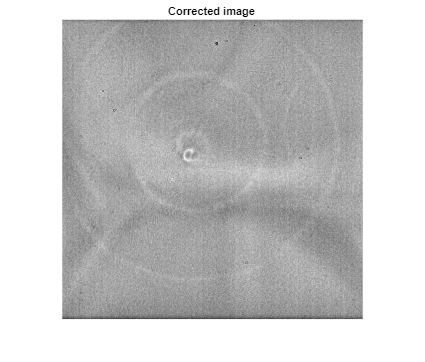


figure;
imshow(corrected_frame2, []);
title('Corrected image ');

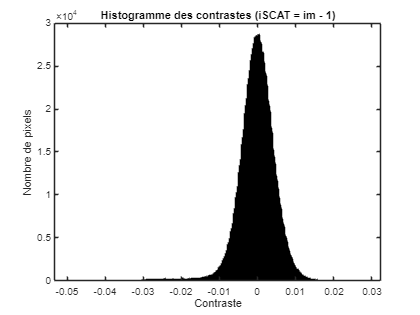

figure;
histogram(frame_now(:) - 1, 400);
title('Histogramme des contrastes (iSCAT = im - 1)');
xlabel('Contraste');
ylabel('Nombre de pixels');

Nombre de minima avant jiggle_spots :
       16346
Spots après nettoyage : 16346
taille spots_lin
       16346           1
taille I_max
       16346           1
taille neighbor_offsets
     1    25
Premier I_max = 1 → décalage = -2402
Spots après jiggle_spots : 16346
Nombre de spots candidats : 6124


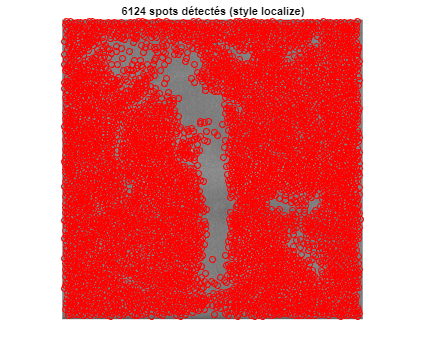

detect_iSCAT_spots_localize_style('MP_data_well10_flatfielded.h5', 'spots_localize_single.h5', 0.02); 

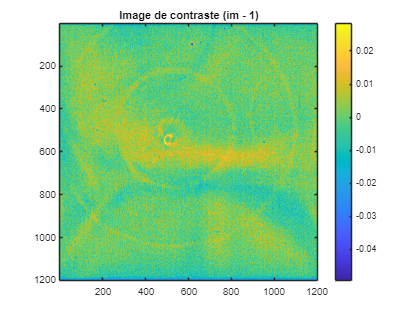

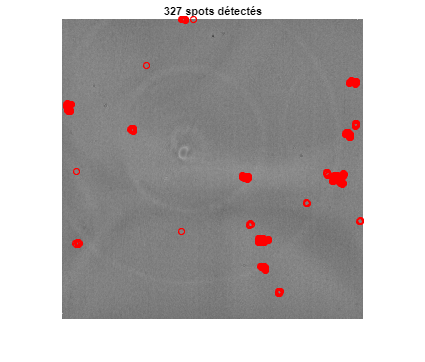


detect_iSCAT_spots_single_v2('MP_data_well10_flatfielded.h5', 'spots_well10.h5', 0.0015);

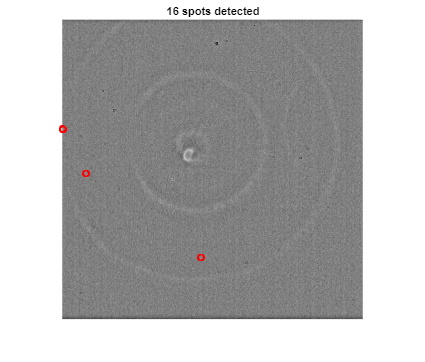

detect_iSCAT_spots_single_2('MP_data_well10.h5', 'spots_well10.h5', 0.005);

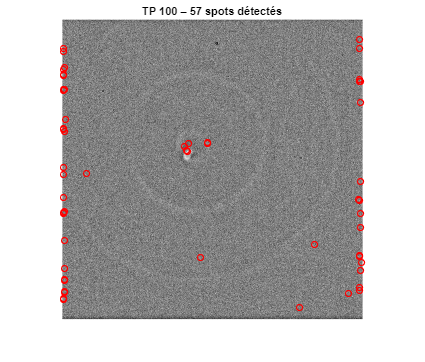

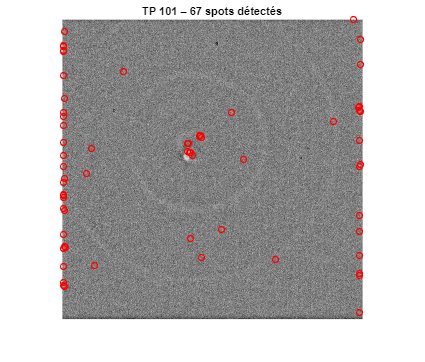


✅ Localisation terminée pour 2 timepoints


candidates = localize_iSCAT_flatfielded('MP_data_.h5', 100:101, 0.002);

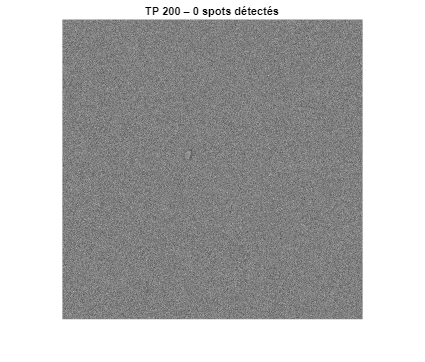

TP 200 : Aucun spot détecté


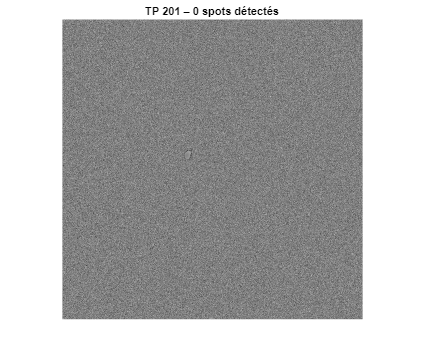

TP 201 : Aucun spot détecté


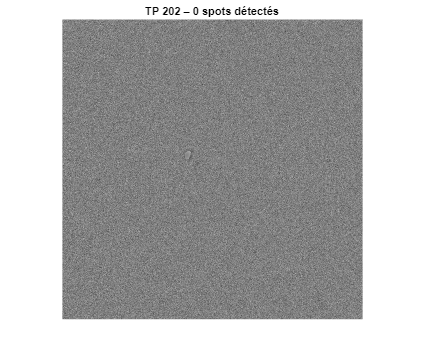

TP 202 : Aucun spot détecté


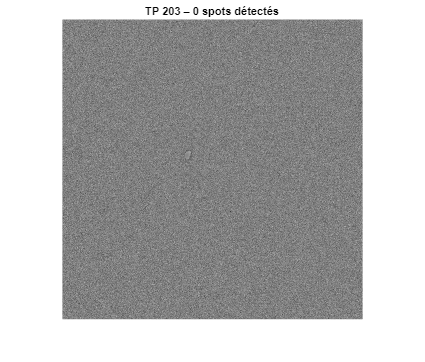

TP 203 : Aucun spot détecté


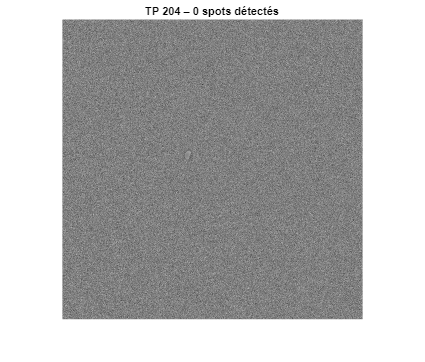

TP 204 : Aucun spot détecté


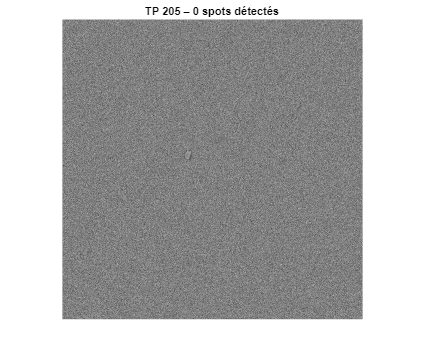

TP 205 : Aucun spot détecté


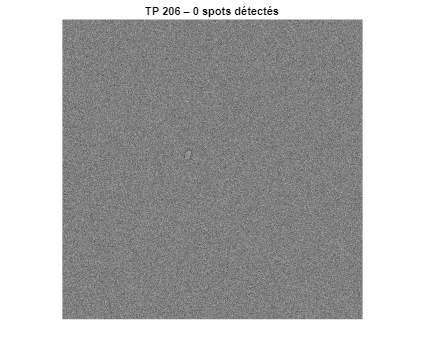

TP 206 : Aucun spot détecté


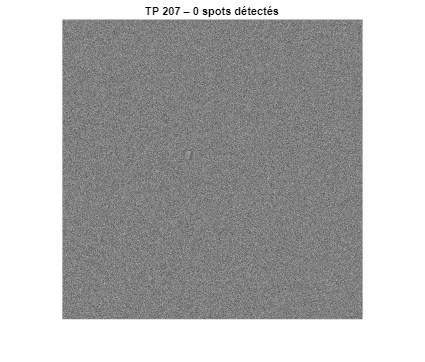

TP 207 : Aucun spot détecté


detect_iSCAT_spots_flatfielded('MP_data_flatfielded_2.h5', 'spots_all_flatfielded.h5', 200:300, 0.005);